# **RS-WISP-07-02: Defense100 Proposal Note with Orbit Throwing**

**WorekerInSpace**

**Hongseok Kim**

## I. Constellation Configuration

### I.1 Add Epoch Information

% %Initial Epoch Definition
% Year = 2025;
% Month = 3;
% Day = 21;
% Hour = 0;
% Minute = 0;
% Seconds = 0;
% 
% % Duration and Steptime
% duration = days(3);
% steptime = 60;
% 
% startTime = datetime(Year,Month,Day,Hour,Minute,Seconds);
% stopTime = startTime + duration;
% 
% scenario = satelliteScenario(startTime,stopTime,steptime);

### I.2 Satellite Constellation - [4 Orbit Planes, Each for 15 Satellites]

% % Initial Orbit Settings
% Altitude = 500;
% SMA = Altitude * 1000 + 6378000;
% ecc= 1e-5;
% inc = 98;
% AOP = 0;
% number_of_SATs = 15;
% TA = 0:360/number_of_SATs:360-360/number_of_SATs;
% Orbit_propagator = 'SGP4';
% 
% % Number of Satellite for each orbit
% 
% % Orbit 1
% satellite_name = "Client_SAT";
% RAAN = 0;
% satellite_orbit_1 = satellite(scenario,...
%                                SMA * ones(number_of_SATs,1),...
%                                ecc * ones(number_of_SATs,1),...
%                                inc * ones(number_of_SATs,1),...
%                                RAAN * ones(number_of_SATs,1),...
%                                AOP * ones(number_of_SATs,1),...
%                                TA,...
%                                Name = satellite_name +"-" +(1:number_of_SATs), ...
%                                OrbitPropagator = Orbit_propagator);
% 
% SMA = (Altitude+100) * 1000 + 6378000;
% satellite_name = 'WISP_SAT';
% wisp_sat = satellite(scenario,SMA,ecc,inc,RAAN,AOP,0, Name = satellite_name, OrbitPropagator=Orbit_propagator);
% wisp_sat.Orbit.LineColor = 'r';
% satellites = scenario.Satellites;
% 
% ac = access(satellites(1:15), satellites(16));
% 
% play(scenario)

## II. RPO scenario Configuration

clear;clc;
addpath('C:\Users\user\Desktop\Redstone_WISP\RS_WISP_05_RPOD_Functions')

%Initial Epoch Definition
Year = 2025;
Month = 3;
Day = 21;
Hour = 0;
Minute = 0;
Seconds = 0;

% Target Information
Target.a = 6880.693;
Target.e = 0.00062680;
Target.i = 97.3728;
Target.RAAN = 296.3138;
Target.AOP = 65.9108;
Target.TA = 294.2783;

% Chaser Information
Chaser.a = 6980.693;
Chaser.e = 0.00062680;
Chaser.i = 97.3728;
Chaser.RAAN = 296;
Chaser.AOP = 65.9108;
Chaser.TA = 296;


% Initialize target and chaser rv data matrix
r_eci_target_data = [];
v_eci_target_data = [];

r_eci_chaser_data = [];
v_eci_chaser_data = [];

r_eci_mothership_data = [];
v_eci_mothership_data = [];

time_vector_data = [];

### III. Mission Sequence

%% Main Algorithm
% Change to ECI frame

% rv data of the target wrt ECI
[r_target, v_target] = kepler2ijk_hs(Target.a, Target.e, Target.i, Target.RAAN, Target.AOP, Target.TA);

% rc data of the chaser wrt ECI
[r_chaser, v_chaser] = kepler2ijk_hs(Chaser.a, Chaser.e, Chaser.i, Chaser.RAAN, Chaser.AOP, Chaser.TA);

r_eci_mothership = r_chaser;
v_eci_mothership = v_chaser;

### III.1 Sequence 1: Two-Impulse Rendezvous toward target

#### 3.1.1 Algorithm for finding optimal delta_t

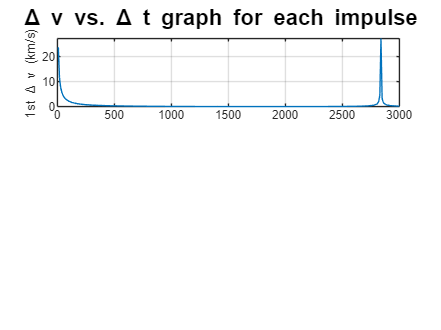

time_of_travel_vec  = 10:10:3000;
Delta_v_info_vec = zeros(length(time_of_travel_vec),1);

for i = 1:length(time_of_travel_vec)
 [Delta_v_0, Delta_v_f, delta_r_t_mat, delta_v_t_mat, v_plus_ECI, t_vector] = two_impulse_rendezvous(r_target, v_target, r_chaser, v_chaser, time_of_travel_vec(i));
 Delta_v_info_vec(i) = norm(Delta_v_0);
end

figure;
subplot(3,1,1)
plot(time_of_travel_vec, Delta_v_info_vec)
% title('First Impulse \Delta t vs. \Delta v','FontSize',15,'FontWeight','bold')
% xlabel('\Delta t (sec)')
ylabel('1st \Delta v (km/s)')
grid on
sgtitle('\Delta v vs. \Delta t graph for each impulse','FontSize',15,'FontWeight','bold')

minimum_Delta_v = min(Delta_v_info_vec);
optimized_delta_t_index = find(Delta_v_info_vec == minimum_Delta_v);
selected_t_f = time_of_travel_vec(optimized_delta_t_index)

selected_t_f = 1810

#### 3.1.2 Get Delta_v by running the function

% Timing of Docking
t_f = selected_t_f;
[Delta_v_0, Delta_v_f, delta_r_t_mat, delta_v_t_mat, v_plus_ECI, t_vector] = two_impulse_rendezvous(r_target, v_target, r_chaser, v_chaser, t_f);

Delta_v_0

Delta_v_0 =    -0.0022
   -0.0336
    0.0208



fprintf('1st Proplusion normalized Delta V: %4.3f (m/s)',norm(Delta_v_0*1000))

1st Proplusion normalized Delta V: 39.575 (m/s)

### IV.1 Data Display

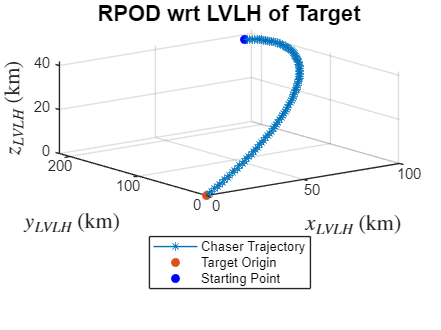

figure;
plot3(delta_r_t_mat(:,1),delta_r_t_mat(:,2),delta_r_t_mat(:,3),'*-')
hold on
scatter3(0,0,0,'filled','o')
scatter3(delta_r_t_mat(1,1),delta_r_t_mat(1,2),delta_r_t_mat(1,3),'filled','o','MarkerFaceColor','blue')
hold off
grid on
title('RPOD wrt LVLH of Target','FontSize',15,'FontWeight','bold')
xlabel('$x_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
ylabel('$y_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
zlabel('$z_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
legend('Chaser Trajectory', 'Target Origin','Starting Point','Location','southoutside')

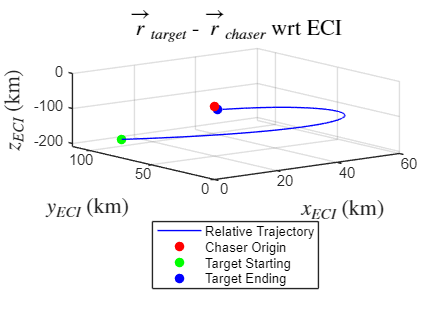





tVec = 1:1:t_f;
n = length(tVec);

% Propaget Target and Chaser under 2-body dynamics
[t,y_chaser] = orbit_propagation(r_chaser, v_plus_ECI, tVec);
[t,y_target] = orbit_propagation(r_target, v_target, tVec);

% y_chaser(end,:);
% y_target(end,:);
% y_chaser(end,1:3) - y_target(end,1:3);

figure;
hold on
plot3(y_target(:,1)-y_chaser(:,1),y_target(:,2)-y_chaser(:,2),y_target(:,3)-y_chaser(:,3),'Color','b')
scatter3(0,0,0,'filled',MarkerEdgeColor='r',MarkerFaceColor='r')
scatter3(y_target(1,1)-y_chaser(1,1),y_target(1,2)-y_chaser(1,2),y_target(1,3)-y_chaser(1,3),'filled',MarkerEdgeColor='g',MarkerFaceColor='g')
scatter3(y_target(end,1)-y_chaser(end,1),y_target(end,2)-y_chaser(end,2),y_target(end,3)-y_chaser(end,3),'filled',MarkerEdgeColor='b',MarkerFaceColor='b')
hold off
grid on
title('$\vec r_{target}$ - $\vec r_{chaser}$ wrt ECI', 'Interpreter', 'latex','FontSize',15)
xlabel('$x_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)
ylabel('$y_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)
zlabel('$z_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)
legend('Relative Trajectory','Chaser Origin','Target Starting','Target Ending','Location','southoutside')
view(3);

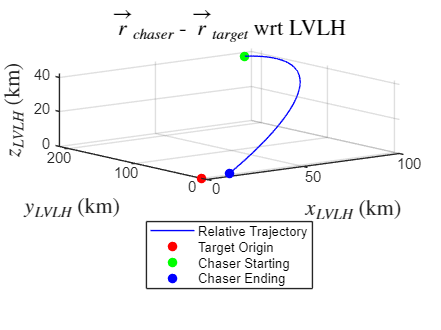





delta_r_LVLH_mat = zeros(length(y_target(:,1)),3);

for i = 1:length(y_target(:,1))
  r_eci = y_target(i,1:3)';
  v_eci = y_target(i,4:6)';
  delta_r_eci = (y_chaser(i,1:3) - y_target(i,1:3))';
  delta_r_LVLH = eci2lvlh(delta_r_eci, r_eci, v_eci);
  delta_r_LVLH_mat(i,:) = delta_r_LVLH';
end


figure;
hold on
plot3(delta_r_LVLH_mat(:,1),delta_r_LVLH_mat(:,2),delta_r_LVLH_mat(:,3),'Color','b')
scatter3(0,0,0,'filled',MarkerEdgeColor='r',MarkerFaceColor='r')
scatter3(delta_r_LVLH_mat(1,1),delta_r_LVLH_mat(1,2),delta_r_LVLH_mat(1,3),'filled',MarkerEdgeColor='g',MarkerFaceColor='g')
scatter3(delta_r_LVLH_mat(end,1),delta_r_LVLH_mat(end,2),delta_r_LVLH_mat(end,3),'filled',MarkerEdgeColor='b',MarkerFaceColor='b')
hold off
grid on
title('$\vec r_{chaser}$ - $\vec r_{target}$ wrt LVLH', 'Interpreter', 'latex','FontSize',15)
xlabel('$x_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
ylabel('$y_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
zlabel('$z_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
legend('Relative Trajectory','Target Origin','Chaser Starting','Chaser Ending','Location','southoutside')
view(3);

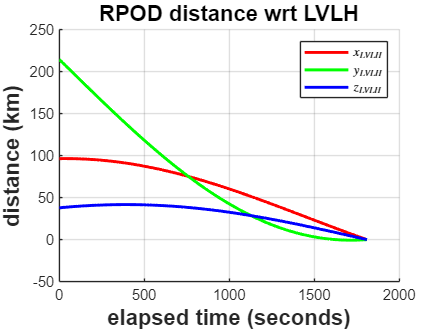



figure;
hold on
plot(t_vector, delta_r_t_mat(:,1),'r','LineWidth',2)
plot(t_vector, delta_r_t_mat(:,2),'g','LineWidth',2)
plot(t_vector, delta_r_t_mat(:,3),'b','LineWidth',2)
hold off
title('RPOD distance wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
ylabel('distance (km)','FontSize',15,'FontWeight','bold')
legend('$x_{LVLH}$','$y_{LVLH}$','$z_{LVLH}$', 'Interpreter', 'latex','Location','northeast')
grid on

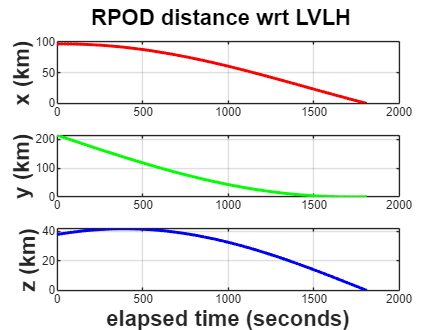


figure;
subplot(3,1,1)
plot(t_vector, delta_r_t_mat(:,1),'r','LineWidth',2)
ylabel('x (km)','FontSize',15,'FontWeight','bold')
grid on
subplot(3,1,2)
plot(t_vector, delta_r_t_mat(:,2),'g','LineWidth',2)
ylabel('y (km)','FontSize',15,'FontWeight','bold')
grid on
subplot(3,1,3)
plot(t_vector, delta_r_t_mat(:,3),'b','LineWidth',2)
ylabel('z (km)','FontSize',15,'FontWeight','bold')
sgtitle('RPOD distance wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
grid on

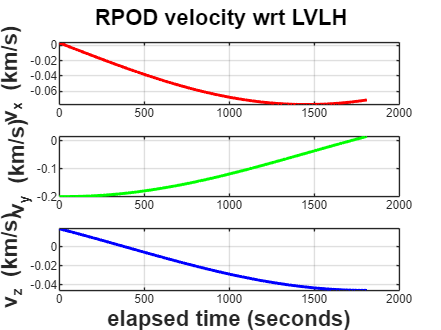



figure;
subplot(3,1,1)
plot(t_vector, delta_v_t_mat(:,1),'r','LineWidth',2)
ylabel('v_x (km/s)','FontSize',15,'FontWeight','bold')
grid on
subplot(3,1,2)
plot(t_vector, delta_v_t_mat(:,2),'g','LineWidth',2)
ylabel('v_y (km/s)','FontSize',15,'FontWeight','bold')
grid on
subplot(3,1,3)
plot(t_vector, delta_v_t_mat(:,3),'b','LineWidth',2)
ylabel('v_z (km/s)','FontSize',15,'FontWeight','bold')
sgtitle('RPOD velocity wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
grid on

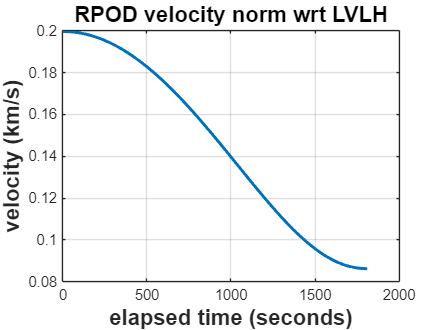



delta_v_t_norm = zeros(length(t_vector),1);
delta_r_t_norm = zeros(length(t_vector),1);

for i = 1:length(t_vector)
  delta_v_t_norm(i) = norm(delta_v_t_mat(i,:));
  delta_r_t_norm(i) = norm(delta_r_t_mat(i,:));
end

figure;
plot(t_vector, delta_v_t_norm,'LineWidth',2)
title('RPOD velocity norm wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
ylabel('velocity (km/s)','FontSize',15,'FontWeight','bold')
grid on

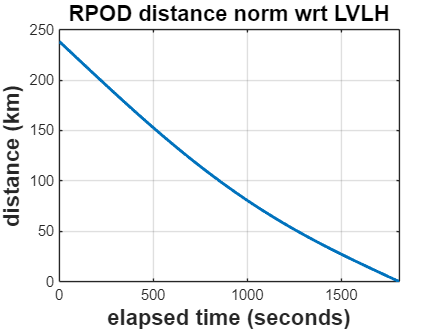


figure;
plot(t_vector, delta_r_t_norm,'LineWidth',2)
title('RPOD distance norm wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
ylabel('distance (km)','FontSize',15,'FontWeight','bold')
xlim([0,t_f])
grid on

## Appendix 1: Bundle functions (kepler2ijk, ijk2kepler)

function [r,v] = kepler2ijk_hs(a,e,inc,RAAN,AOP,theta)

mu = 398600.4415;

RAAN = RAAN/180*pi;
inc = inc/180*pi;
AOP = AOP/180*pi;
theta = theta/180*pi;


R_3_AOP = [cos(AOP), sin(AOP),0;
           -sin(AOP), cos(AOP),0;
                    0,       0,1];

R_1_inc = [1,       0,         0;
           0, cos(inc),  sin(inc);
           0,-sin(inc),  cos(inc)];

R_3_RAAN = [cos(RAAN), sin(RAAN),0;
           -sin(RAAN), cos(RAAN),0;
                    0,       0,1];


Q_rotation = R_3_AOP * R_1_inc * R_3_RAAN;

p = Q_rotation(1,:);
q = Q_rotation(2,:);
w = Q_rotation(3,:);

p_value = a*(1-e^2);
r = p_value* (cos(theta)*p + sin(theta) *q)/(1+e*cos(theta));
r = r';
v = sqrt(mu/p_value)*(-sin(theta)*p+(e+cos(theta))*q)';
end


function [a, e, inc, RAAN, AOP, theta] = ijk2kepler_hs(r,v)

mu = 398600.4415;

h = cross(r,v);                                   % Angular Velocity Vector
z = [0,0,1]';
n = (cross(z,h))/(norm(cross(z,h)));              % Normal Vector
e_vector = ((cross(v,h))/mu) - r/(norm(r));       % Eccentricity vector


a = (-mu)/((norm(v))^2 - 2*mu/norm(r));           % 1. Semi-major axis
e = norm(e_vector);                               % 2. Eccentricity
inc = acos(dot(z,h)/norm(h)) / pi *180;           % 3. Inclination

RAAN = atan2(n(2),n(1));                          % 4. RAAN
RAAN = RAAN / pi * 180;

AOP = acos((dot(n,e_vector))/norm(e_vector));                   % 5. Argument of periapse
if(e_vector(3)<0)
    AOP = 2*pi - AOP;
end
AOP = AOP/pi*180;

theta = acos((dot(r,e_vector))/(norm(r)*norm(e_vector)));       % 6. True anomaly
if(dot(r,v) < 0)
    theta = 2*pi-theta;
end
theta = theta / pi * 180;

end